clear all;
clc;
close all;

full_path = which("rice.png");
if (isempty(full_path))
    error('Image file not found in the current path.');
end
img = imread(full_path);

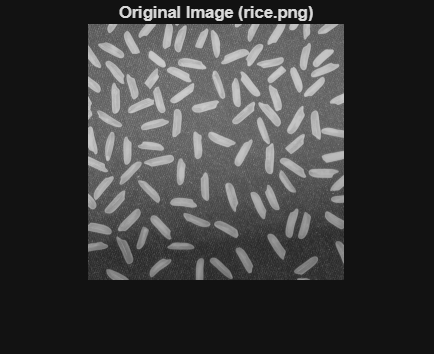

figure;
    imshow(img);
    title('Original Image (rice.png)');

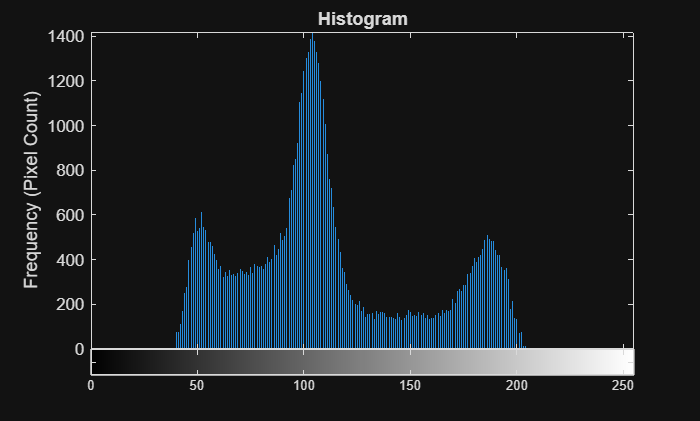

% Display the histogram
figure;
    imhist(img);
    ylabel('Frequency (Pixel Count)');
    title('Histogram');
    axis tight;

การหาค่าทาง สถิติของรูปภาพ

% Get the dimensions (Height x Width)
[height, width] = size(img);
fprintf('Size: %d rows × %d columns\n', height, width);

Size: 256 rows × 256 columns


% Get the intensity range
fprintf('Min intensity: %d\n', min(img(:)));

Min intensity: 40


fprintf('Max intensity: %d\n', max(img(:)));

Max intensity: 204


% Get the mean (average) intensity
fprintf('Mean intensity: %.2f\n', mean(img(:)));

Mean intensity: 111.25


pixel_value = img(100, 150);
fprintf('The pixel value at (100, 150) is: %d\n', pixel_value);

The pixel value at (100, 150) is: 177


modify_img = img;
disp(size(img));

   256   256



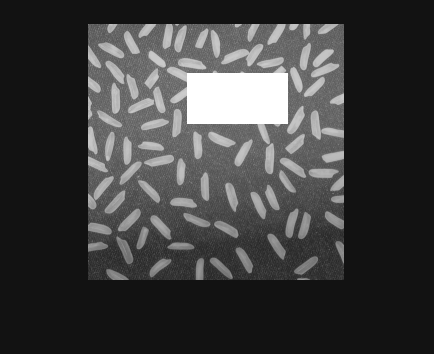

modify_img(50:100,100:200) = 255;
figure;
    imshow(modify_img);

การเพิ่มค่าความสว่าง ต้องปรับสเกลให้เป็น 0->1 ก่อน หรือก็คือปรับเป็น double นั้นแหละ

To create a "negative" of the image, we do the same process. The "negative" of an image in the [0, 1] range is `1.0 - value`.

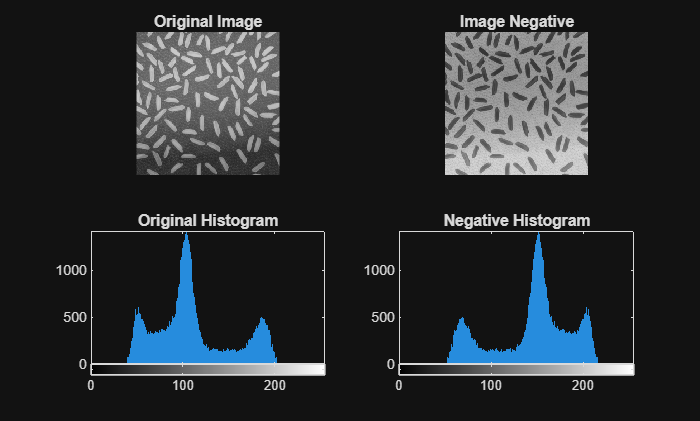

% 1. We already have img_double from the previous step
%    (If running this section alone, uncomment the next two lines)
% img = imread(which('rice.png'));
% img_double = im2double(img);

% 2. Subtract every pixel value from 1.0
img_negative_double = 1.0 - img_double;

% 3. Convert back to uint8
img_negative_uint8 = im2uint8(img_negative_double);

% --- Display Results ---
figure;
    subplot(2, 2, 1);
        imshow(img);
        title('Original Image');

    subplot(2, 2, 2);
        imshow(img_negative_uint8);
        title('Image Negative');

    subplot(2, 2, 3);
        imhist(img);
        title('Original Histogram');
        axis tight;

    subplot(2, 2, 4);
        imhist(img_negative_uint8);
        title('Negative Histogram');
        axis tight;